# Full pipeline

## System matrices

A = [0 1 0 ; 0 0 1; -0.25 0.75 0.25];
B = [0;0;1];
[V,L] = eig(A^2-A);
F = V(:,2);  % Ensures (A,F) is not controllable - our results do not require it.
C = [1 0 0; 0 1 0];
nu = 1;
nv = 1;
ny = 2;
nx = 3;
D = [0; 0];
G = [0; 0];

dt = 1;

% Systems
St = ss(A, [B,F], C, [D,G], dt);  % Total
S = ss(A, F, C, G, dt);  % Residual

## Input data

rng(1907);

t = 0:dt:1000;
Nt = length(t);
u = randn(size(t));
% No fixed frequency content, hard to predict
f = (sin(0.25*t.^1.3)) + 0.1 + 0*randn(size(t));


## Simulation

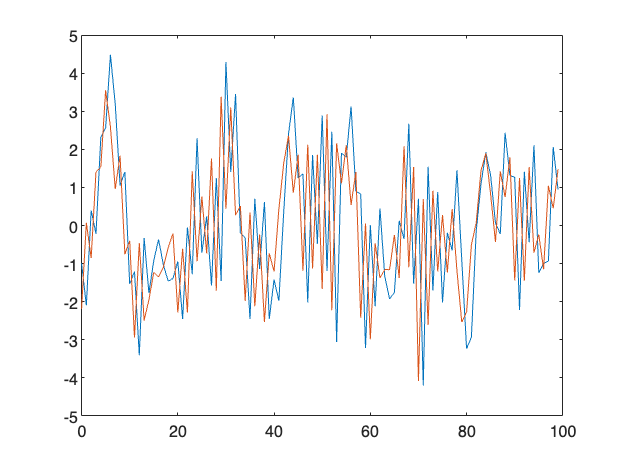

x0 = randn(nx,1);
y = lsim(St, [u;f], [], x0);
plot(t(1:100),y(1:100,:));

## PI-MOESP for (A,B,C,D)

% Build hankel matrices
s = 30;
[AT, BT, CT, DT] = pi_moesp(u', y, s, nx);

## Make residual

% Using real A,B,C,D
xi0 = randn(nx,1);  % We can choose a random xi(0)
Sio = ss(A, B, C, D, dt);
yio = lsim(Sio, u, [], xi0);
r = y - yio;

% Using recovered A,B,C,D
Sio_id = ss(AT, BT, CT, DT, dt);
Sio_id = compreal(Sio_id, "o");
yio_id = lsim(Sio_id, u, [], xi0);
r_id = y - yio_id;

## Fault reconstruction via the exact method

% Find nu
s = 20;  % Large value
Rs = blkhankel(r,s);
Rsn = blkhankel(r,s+1);
nvr = rank(Rsn) - rank(Rs)

nvr = 1


% Find smallest s such that we can apply our method
s = 1;
R = blkhankel(r,s);
for s = 2:5
    Rn = blkhankel(r,s);
    if rank(Rn) - rank(R) == nvr
        break;
    else
        R = Rn;
    end
end
R = Rn;

O = extended_obs(S.A, S.C, s);

[Uy,Sy,Vy] = svd(R,"econ");
thr = 0;
ranky = sum(diag(Sy)>1e-10+thr);  % this seems to work well, but requires having an estimate of the noise levels
Uy = Uy(:,1:ranky);

FGr = estimate_input_matrices(Uy,O,ny)

FGr =    -0.0000    0.9378
   -0.0000    0.3278
   -0.0000    0.1146
   -0.9440   -0.0000
   -0.3300   -0.0000


## Fault reconstruction via the exact method - using identified system

% Find nu
s = 5;  % Large value
Rs = blkhankel(r_id,s);
Rsn = blkhankel(r_id,s+1);
nvr = rank(Rsn,1.0) - rank(Rs,1.0)  % By inspection, svs drop below 1

nvr = 1

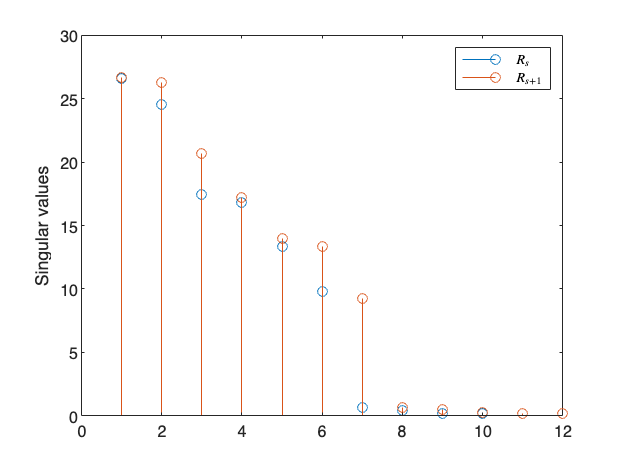

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


close all;
stem(svd(Rs)); hold all; stem(svd(Rsn))
legend('$R_s$','$R_{s+1}$','Interpreter','Latex');
ylabel('Singular values');
matlab2tikz('svs.tex')


% Find smallest s such that we can apply our method
s = 1;
R = blkhankel(r,s);
for s = 2:5
    Rn = blkhankel(r,s);
    if rank(Rn) - rank(R) == nvr
        break;
    else
        R = Rn;
    end
end
R = Rn;

O = extended_obs(Sio_id.A, Sio_id.C, s);

[Uy,Sy,Vy] = svd(R,"econ");
ranky = sum(diag(Sy)>1e-10);
Uy = Uy(:,1:ranky);

FGr = estimate_input_matrices(Uy,O,ny)

FGr =    -0.0000    0.9332
   -0.0000    0.3379
   -0.0000    0.1223
   -0.9440   -0.0000
   -0.3300   -0.0000
